clear
addpath('Assignments'); addpath('frffit'); addpath('Assignment 2\')
%simulation variables
fs = 1000

fs = 1000

stepsize = 1/fs

stepsize = 1.0000e-03

max_freq = log10(fs/2) 

max_freq = 2.6990

t_end = 30; %[s]

n_sampling = t_end * fs;

min_freq = 1; %Hz lowest desired sampling frequency
windowsize = 1/min_freq; %[s] window size in seconds
window = windowsize*fs; %window size in data points
nfft = window/min_freq; 
n_overlap = window/4;

%running simulation and loading data
out = sim("frf_ex3");

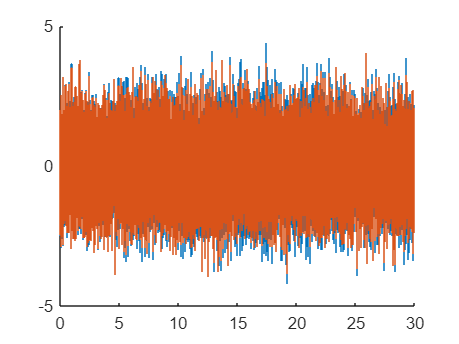

d = out.d;
u = out.u;

figure()
hold on
plot(u)
plot(d)

hold off

2)

%creating transfer function estimate

[Sud, F] = tfestimate(d.Data,u.Data,window,n_overlap,nfft,fs); %cross spectral power density
Sdd = pwelch(d.Data,window); %spectral power disturbance
Suu = pwelch(u.Data,window); %spectral power input
%S =  Sud./Sdd; %sensitivity function
S = Sud

S =   -0.1466 + 0.0000i
   0.3623 + 0.7529i
   0.9579 + 0.5592i
   1.0435 + 0.2758i
   1.0246 + 0.1890i
   1.0224 + 0.1510i
   1.0144 + 0.1198i
   1.0136 + 0.1032i
   1.0077 + 0.0845i
   1.0087 + 0.0788i


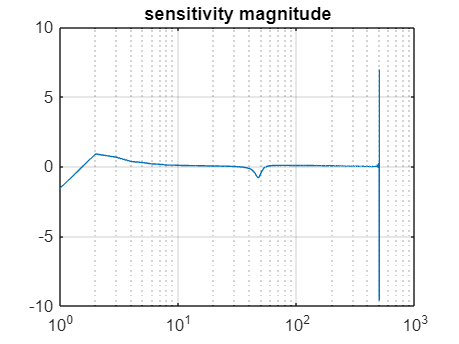

semilogx(F,mag2db(abs(S)))
title("sensitivity magnitude")
grid on

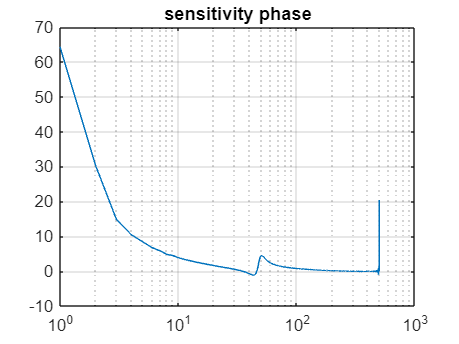


semilogx(F,angle(S)/pi*180)
title('sensitivity phase')
grid on

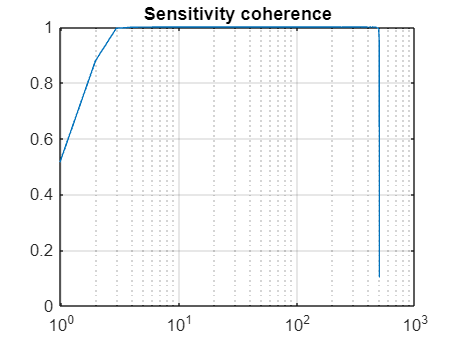


%plotting coherence 
[coherence_ry, f] = mscohere(d.Data,u.Data,window,[],[],fs);
semilogx(f,coherence_ry)
title('Sensitivity coherence')
grid on

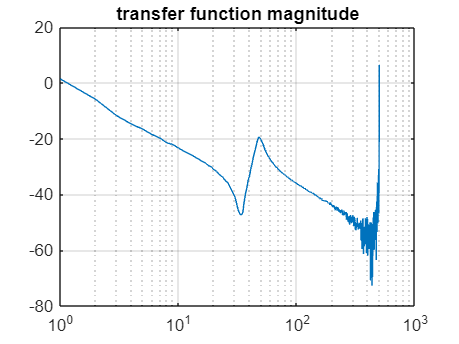


L = 1./S-1;
semilogx(F,mag2db(abs(L)))
title('transfer function magnitude')
grid on

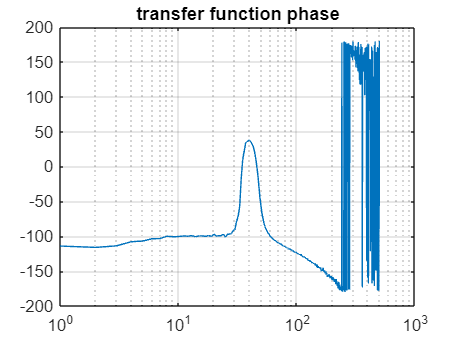


semilogx(F,angle(L)/pi*180)
title('transfer function phase')
grid on

3) proces sensitivity (y/d)

y = out.y %loading y data

  timeseries

  Common Properties:
            Name: ''
            Time: [30001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [30001x1 double]
        DataInfo: 


sampling_freq = 0.25; %Hz lowest desired sampling frequency
nfft = 1/sampling_freq*window;
n_overlap = window/2;

[Syd, F] = tfestimate(d.Data,y.Data,window,n_overlap,nfft,fs); %cross spectral power density
Sdd = pwelch(d.Data,window); %spectral power disturbance
Suu = pwelch(u.Data,window); %spectral power input
%S =  Sud./Sdd; %sensitivity function
S = Syd

S = 1.0e+03 *

   3.1692 + 0.0000i
   2.8746 - 1.2038i
   2.1183 - 2.0732i
   1.1752 - 2.4687i
   0.2925 - 2.4398i
  -0.3807 - 2.1154i
  -0.7824 - 1.6297i
  -0.9150 - 1.1038i
  -0.8415 - 0.6488i
  -0.6755 - 0.3409i


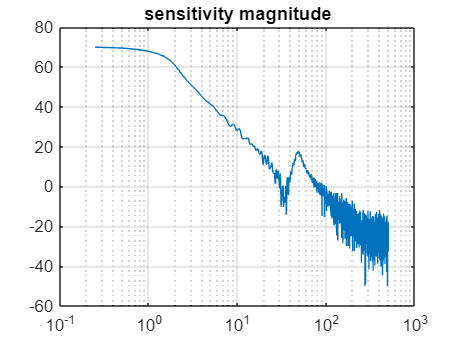

semilogx(F,mag2db(abs(S)))
title("sensitivity magnitude")
grid on

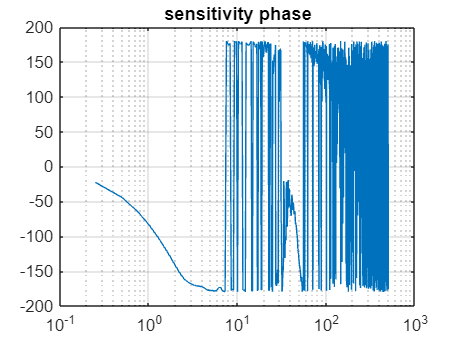


semilogx(F,angle(S)/pi*180)
title('sensitivity phase')
grid on

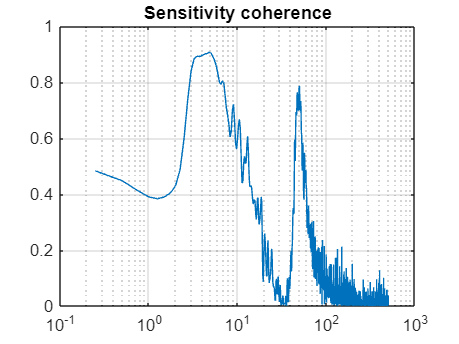


[coherence_ry, f] = mscohere(d.Data,y.Data,window,n_overlap,nfft,fs);
semilogx(f,coherence_ry)
title('Sensitivity coherence')
grid on